%  
% Sound
% IIT BOMBAY campus recorded mosque sound 
% Length :- 60 sec
% Recorded with sony PCM D50

[samples, fsample] = audioread('TestAudio5.wav');

player = audioplayer(samples, fsample);
play(player);


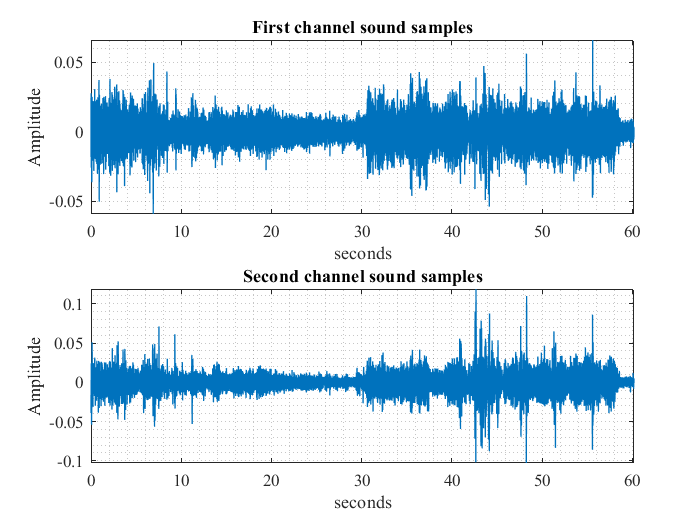

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

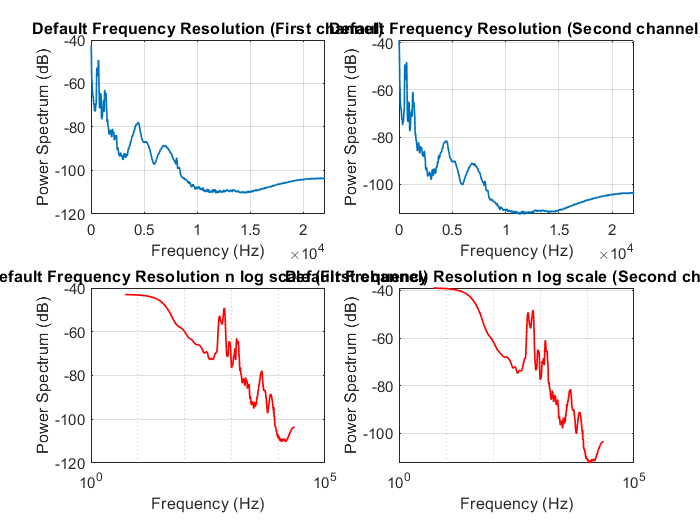


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);
% Because it is too large size audio recording hence, spectrogram would
% take too much time

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.065887
Max value in second Channel = 0.1189
Minimum value in first Channel = -0.059326
Minimum value in second Channel = -0.10281
Mean value in first channel = -2.759e-05
Mean value in second channel= -3.5261e-05
standard deviation of first channel= 0.0084044
standard deviation of second channel= 0.011692
Variance of first channel= 7.0634e-05
Variance of second channel= 0.00013671
Power in first channel in dB= -41.5098
Power in second channel in dB= -38.6421
Sampling frequency in Hz =44100


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



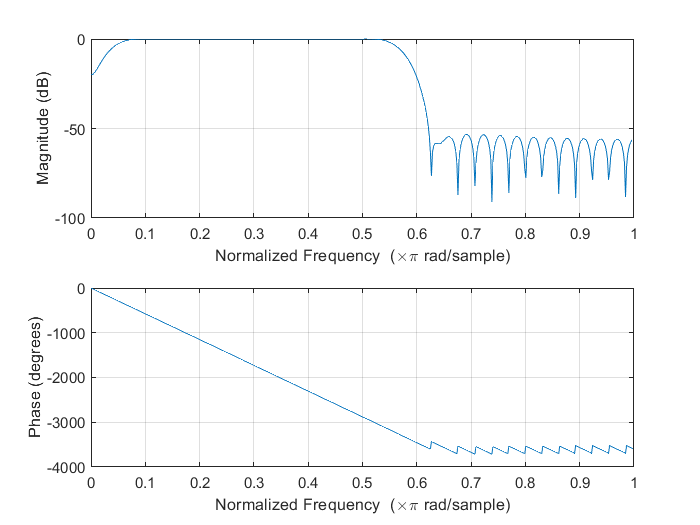

% Audio Enhancement techniques

% bandpass filter 
order =64;
level =0.1;
resultAudio = bandpassVocalFilter(samples, order,fsample, level);

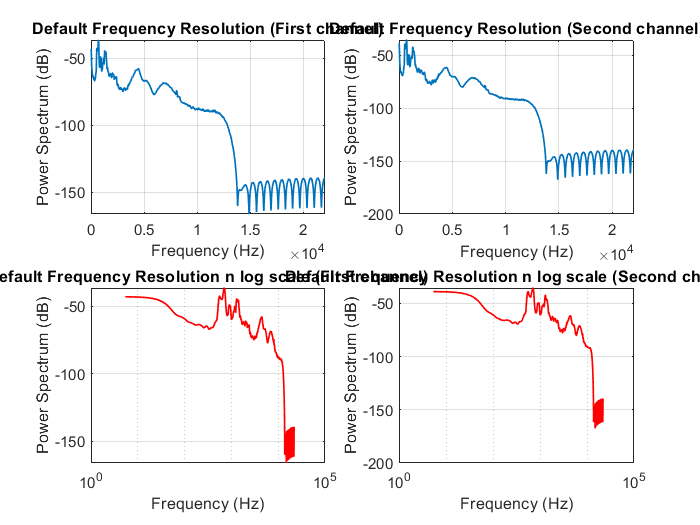


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample, 0.05);

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


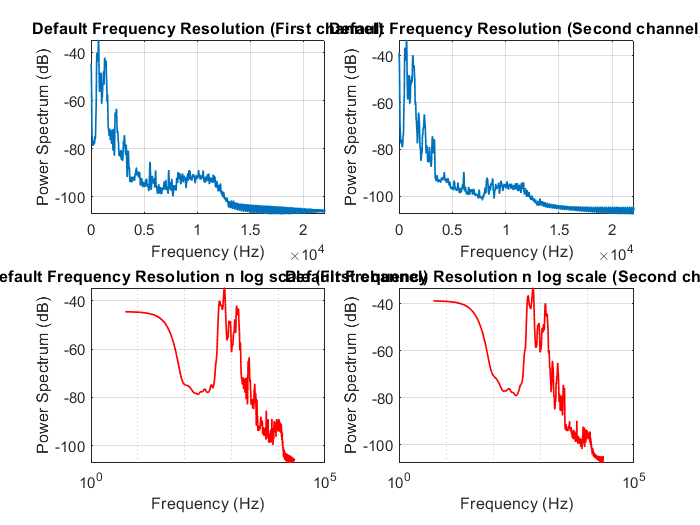


player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

% Compressor 
% 
% dRC = compressor(-20,5,'SampleRate',fsample);
% visualize(dRC)
% 
% resultAudio3 = dRC(resultAudio2);
% 
% player = audioplayer(resultAudio3, fsample);
% play(player);
% 
% ShowPSD2(resultAudio3, fsample);


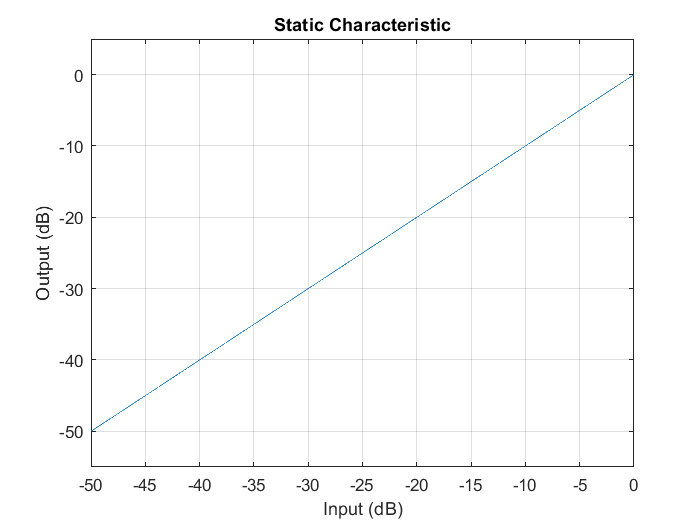

% Expender

dRC = expander(-90, 7.5, 'SampleRate',fsample);
visualize(dRC);

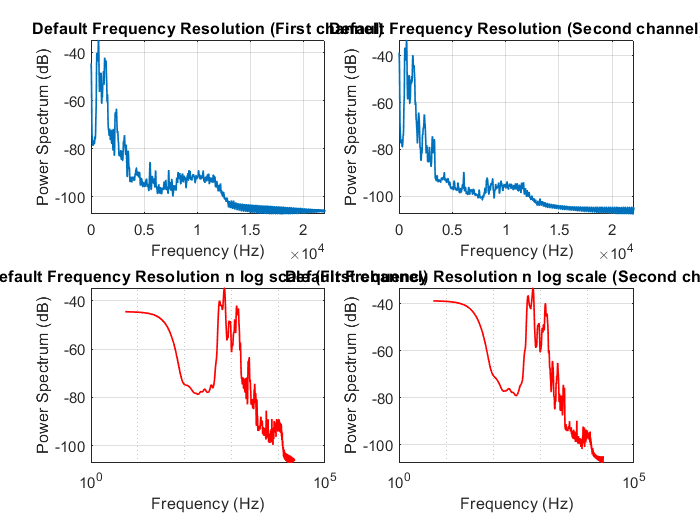


resultAudio4 = dRC(resultAudio2);


player = audioplayer(resultAudio4, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);


audiowrite('enhancedTestAudio5b.wav', resultAudio2, fsample);
audiowrite('enhancedTestAudio5.wav', resultAudio4, fsample);
